# Create Incremental Learner Without Any Prior Information

Create a default incremental linear model for regression.


maefcn = @(z,zfit)abs(z - zfit);
maemetric = struct("MeanAbsoluteError",maefcn);

Mdl = incrementalRegressionLinear(  ...
    'Solver','sgd','Lambda',0.001,'BatchSize',20,'LearnRate',0.002, ...
    'Standardize',false, ...
    'MetricsWarmupPeriod',100,'MetricsWindowSize',50, ...
    'Learner','leastsquares', ...
    'Metrics',{ 'mse' maemetric})

Mdl =   incrementalRegressionLinear

               IsWarm: 0
              Metrics: [2×2 table]
    ResponseTransform: 'none'
                 Beta: [0×1 double]
                 Bias: 0
              Learner: 'leastsquares'


  Properties, Methods


`Mdl` is an `incrementalRegressionLinear` model object. All its properties are read-only.

`Mdl` must be fit to data before you can use it to perform any other operations. The software sets the estimation period to 1000 because half the width of the epsilon insensitive band `Epsilon` is unknown. You can set `Epsilon` to a positive floating-point scalar by using the `Epsilon` name-value argument. This action results in a default estimation period of 0.

Load the robot arm data set.

%load robotarm
idxTestAll

idxTestAll =         4962        4963        4964        4965        4966        4967        4968        4969        4970        4971        4972        4973        4974        4975        4976        4977        4978        4979        4980        4981        4982        4983        4984        4985        4986        4987        4988        4989        4990        4991        4992        4993        4994        4995        4996        4997        4998        4999        5000        5001        5002        5003        5004        5005        5006        5007        5008        5009        5010        5011


idxTestAll_batIndex

idxTestAll_batIndex =     16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16


idxTestAll_batIndex1 = (idxTestAll_batIndex == 16)

idxTestAll_batIndex1 = 1×8418 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


idxTest

idxTest =     76    48    62    28    26    47    16    99    92   106    84   119


idxAll

idxAll =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50



find(idxTestAll_batIndex == idxTest(7))

ans =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


idxTestAll_test1 = idxTestAll(find(idxTestAll_batIndex == idxTest(7)))

idxTestAll_test1 =         4962        4963        4964        4965        4966        4967        4968        4969        4970        4971        4972        4973        4974        4975        4976        4977        4978        4979        4980        4981        4982        4983        4984        4985        4986        4987        4988        4989        4990        4991        4992        4993        4994        4995        4996        4997        4998        4999        5000        5001        5002        5003        5004        5005        5006        5007        5008        5009        5010        5011



RUL(idxTestAll_test1)

ans =    316
   315
   314
   313
   312
   311
   310
   309
   308
   307


test_bat = idxTest(7)

test_bat = 16

RUL_test = RUL(idxTestAll(find(idxTestAll_batIndex == test_bat)))

RUL_test =    316
   315
   314
   313
   312
   311
   310
   309
   308
   307


Ic_test = Ic(idxTestAll(find(idxTestAll_batIndex == test_bat)),:)

Ic_test =     6.0003    6.0001    5.9997    6.0001    5.9999    6.0006    5.9998    4.1998    3.0000    3.0000    3.0000    2.9999    3.0000    3.0001    2.1289    0.9999    1.0000    0.2383         0         0
    6.0008    6.0005    5.9999    5.9998    5.9997    6.0005    5.9999    4.2002    3.0001    3.0000    3.0000    2.9999    3.0000    3.0000    2.1270    1.0000    1.0000    0.2294         0         0
    5.9998    6.0000    6.0006    6.0002    6.0002    5.9997    6.0003    4.1997    3.0000    3.0000    3.0000    2.9999    3.0002    3.0000    2.1257    1.0000    0.9998    0.2293         0         0
    6.0008    6.0002    5.9999    5.9997    6.0007    6.0004    6.0004    4.1998    3.0002    3.0000    3.0000    3.0000    2.9999    3.0000    2.1274    1.0000    1.0000    0.2238         0         0
    6.0008    6.0002    6.0002    6.0003    6.0001    5.9999    5.9998    4.1998    3.0001    3.0000    2.9999    2.9998    3.0000    3.0000    2.1282    1.0000    0.9999    0.2214      

Vd_test = Vd(idxTestAll(find(idxTestAll_batIndex == test_bat)),:)

Vd_test =     3.2258    3.1679    3.1540    3.1437    3.1333    3.1222    3.1101    3.0969    3.0828    3.0669    3.0481    3.0239    2.9911    2.9419    2.8589    2.6959    2.3086    2.0000    2.0001    2.0001
    3.2253    3.1674    3.1537    3.1432    3.1329    3.1217    3.1095    3.0965    3.0822    3.0664    3.0474    3.0232    2.9902    2.9408    2.8571    2.6928    2.3031    1.9998    1.9997    1.9997
    3.2251    3.1671    3.1535    3.1430    3.1326    3.1215    3.1093    3.0962    3.0820    3.0661    3.0470    3.0229    2.9898    2.9403    2.8565    2.6916    2.3006    2.0001    2.0001    2.0001
    3.2257    3.1676    3.1538    3.1433    3.1329    3.1218    3.1097    3.0964    3.0822    3.0663    3.0473    3.0231    2.9900    2.9404    2.8562    2.6908    2.2958    1.9998    1.9999    1.9999
    3.2259    3.1678    3.1540    3.1435    3.1331    3.1219    3.1097    3.0965    3.0823    3.0665    3.0474    3.0232    2.9901    2.9403    2.8559    2.6899    2.2927    1.9999    2.

For details on the data set, enter `Description` at the command line.

Fit the incremental model to the training data by using the `updateMetricsAndFit` function. To simulate a data stream fit the model in chunks of 50 observations at a time. At each iteration:

- Process 50 observations.

- Overwrite the previous incremental model with a new one fitted to the incoming observations.

- Store $\beta_1$, the cumulative metrics, and the window metrics to see how they evolve during incremental learning.

ytrain = RUL_test;
Xtrain = Vd_test;
% Preallocation
n = numel(ytrain);
numObsPerChunk = 5;%50;
nchunk = floor(n/numObsPerChunk);
ei = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
beta1 = zeros(nchunk,1);    


% Incremental fitting
rng("default"); % For reproducibility
for j = 1:nchunk
    ibegin = min(n,numObsPerChunk*(j-1) + 1);
    iend   = min(n,numObsPerChunk*j);
    idx = ibegin:iend;    
    Mdl = updateMetricsAndFit(Mdl,Xtrain(idx,:),ytrain(idx));
    mse{j,:} = Mdl.Metrics{"MeanSquaredError",:};
    mae{j,:} = Mdl.Metrics{"MeanAbsoluteError",:};
    beta1(j + 1) = Mdl.Beta(1);
end

`IncrementalMdl` is an `incrementalRegressionLinear` model object trained on all the data in the stream. While `updateMetricsAndFit` processes the first 1000 observations, it stores the response values to estimate `Epsilon`; the function does not fit the coefficients until after this estimation period. During incremental learning and after the model is warmed up, `updateMetricsAndFit` checks the performance of the model on the incoming observations, and then fits the model to those observations.

To see how the performance metrics and $\beta_1$ evolve during training, plot them on separate tiles.

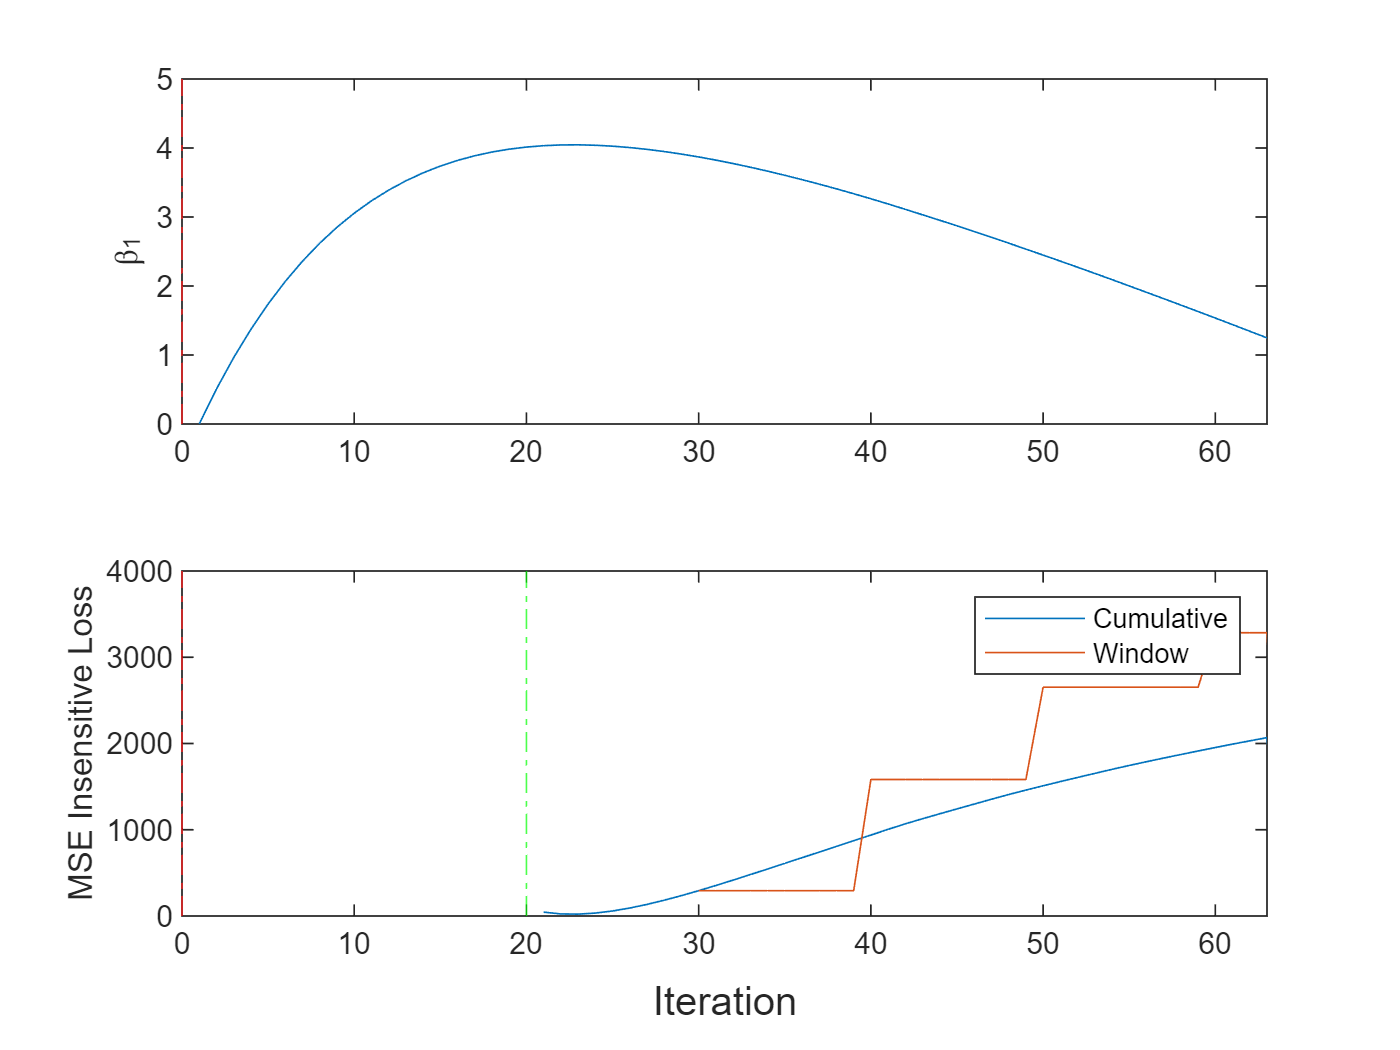

t = tiledlayout(2,1);
nexttile
plot(beta1)
ylabel('\beta_1')
xlim([0 nchunk])
xline(Mdl.EstimationPeriod/numObsPerChunk,'r-.')
nexttile
h = plot(mse.Variables);
xlim([0 nchunk])
ylabel('MSE Insensitive Loss')
xline(Mdl.EstimationPeriod/numObsPerChunk,'r-.')
xline((Mdl.EstimationPeriod + Mdl.MetricsWarmupPeriod)/numObsPerChunk,'g-.')
legend(h,mse.Properties.VariableNames)
xlabel(t,'Iteration')

The plot suggests that `updateMetricsAndFit` does the following:

- After the estimation period (first 20 iterations), fit $\beta_1$ during all incremental learning iterations.

- Compute the performance metrics after the metrics warm-up period only.

- Compute the cumulative metrics during each iteration.

- Compute the window metrics after processing 500 observations (4 iterations).

*Copyright 2020 The MathWorks, Inc.*